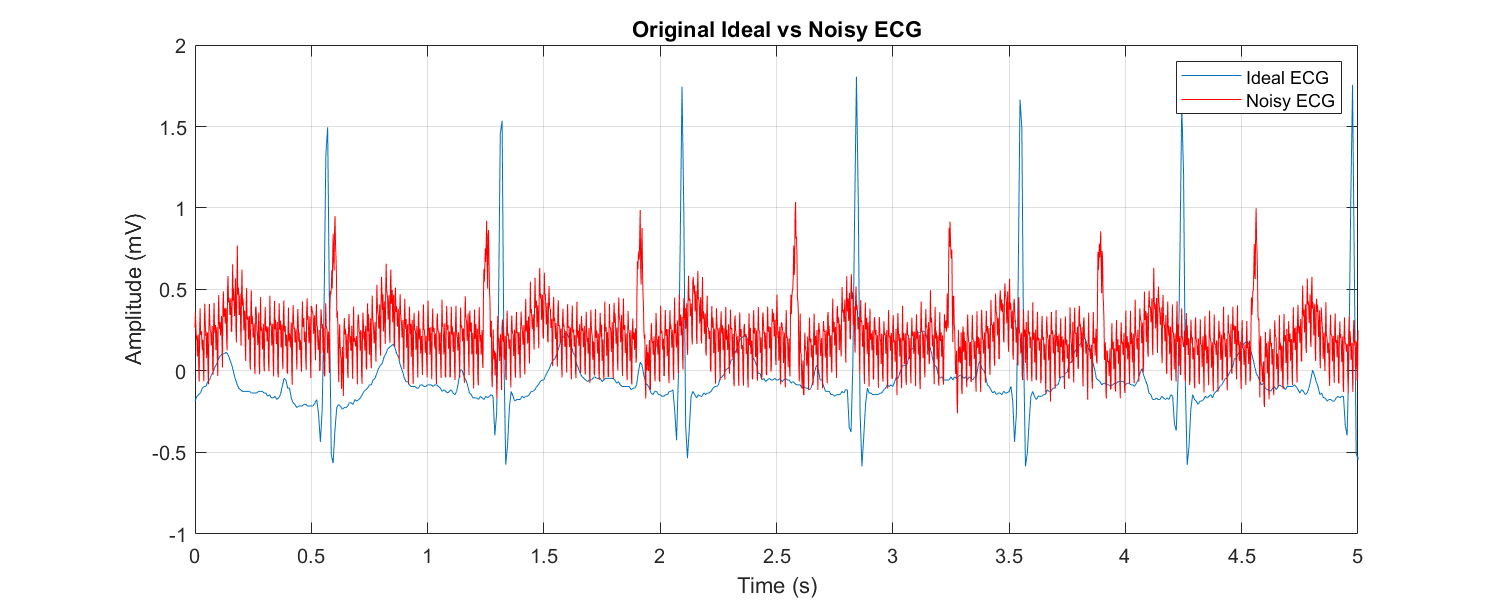

%% 1. Wiener Filter for ECG Denoising


clear; clc; close all;

%% (i) Load and visualize ECG data
% Load the provided noisy and ideal ECG signals
load("ECG_rec (2).mat");
load("idealECG (1).mat");

% Assign local variable names
ecg_noisy = nECG(:);       % Noisy ECG
ecg_clean = idealECG(:);   % Ideal ECG 

% Sampling frequencies
fs_noisy = 500;
fs_clean = 128;

% Time vectors
t_noisy = (0:length(ecg_noisy)-1) / fs_noisy;
t_clean = (0:length(ecg_clean)-1) / fs_clean;

% Compare before upsampling
figure('Position', [100, 100, 1000, 400]);
plot(t_clean, ecg_clean); hold on;
plot(t_noisy, ecg_noisy, 'r');
title('Original Ideal vs Noisy ECG');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
legend('Ideal ECG','Noisy ECG');
xlim([0 5]); grid on;

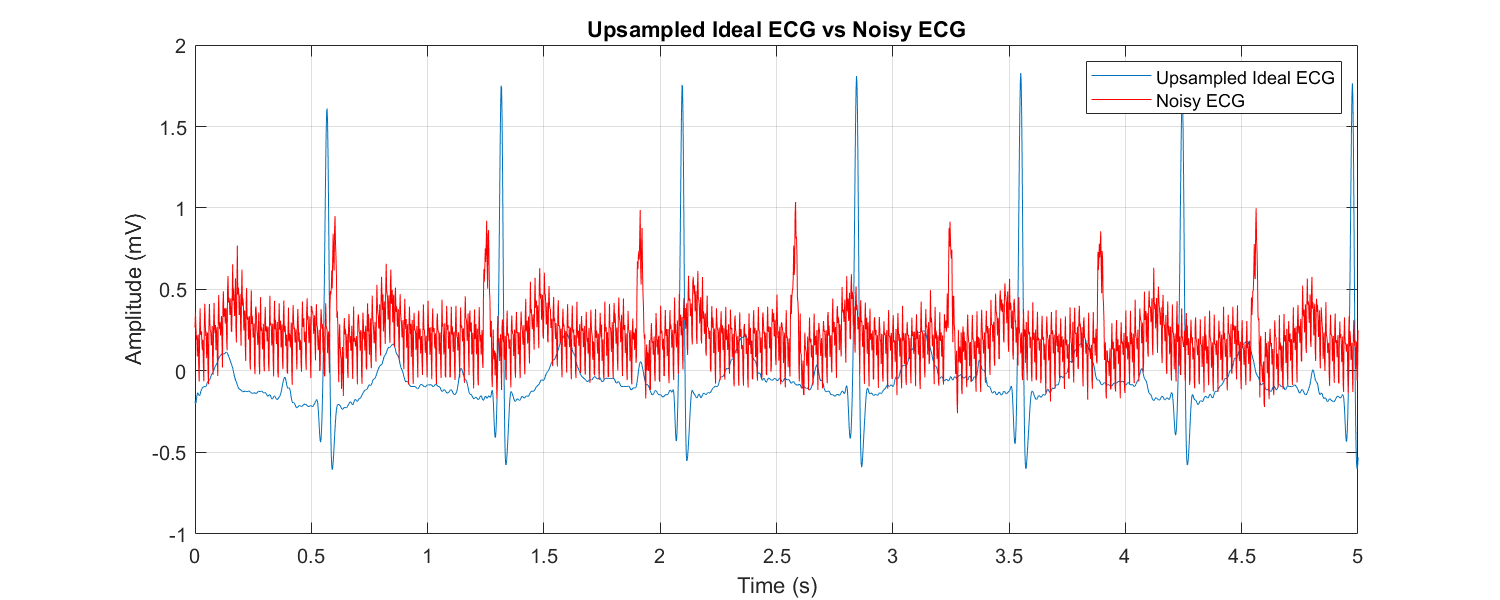


%%Match sampling rates via upsampling
% Compute rational resampling ratio
[p, q] = rat(fs_noisy / fs_clean);

% Upsample clean ECG to match noisy ECG sampling frequency
ecg_clean_up = resample(ecg_clean, p, q);

% Create new time axis
t_clean_up = (0:length(ecg_clean_up)-1) / fs_noisy;

figure('Position', [100, 100, 1000, 400]);
plot(t_clean_up, ecg_clean_up); hold on;
plot(t_noisy, ecg_noisy, 'r');
title('Upsampled Ideal ECG vs Noisy ECG');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
legend('Upsampled Ideal ECG','Noisy ECG');
xlim([0 5]); grid on;

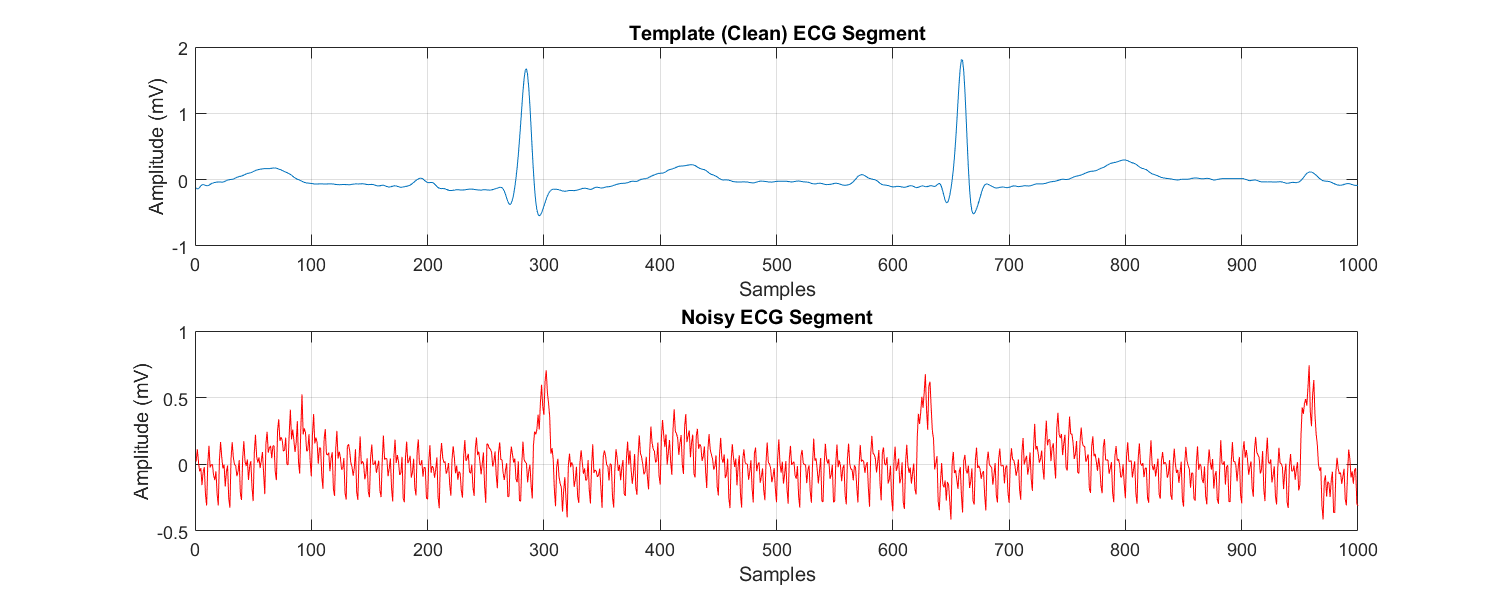


%% Extract short signal segments for filter design
segment_length = 1000;

clean_seg = ecg_clean_up(1:segment_length);
noisy_seg = ecg_noisy(1:segment_length);

% DC offset removal
clean_seg = clean_seg - mean(clean_seg);
noisy_seg = noisy_seg - mean(noisy_seg);

figure('Position', [100, 100, 1000, 400]);
subplot(2,1,1);
plot(clean_seg);
title('Template (Clean) ECG Segment');
xlabel('Samples'); ylabel('Amplitude (mV)');
grid on;

subplot(2,1,2);
plot(noisy_seg,'r');
title('Noisy ECG Segment');
xlabel('Samples'); ylabel('Amplitude (mV)');
grid on;

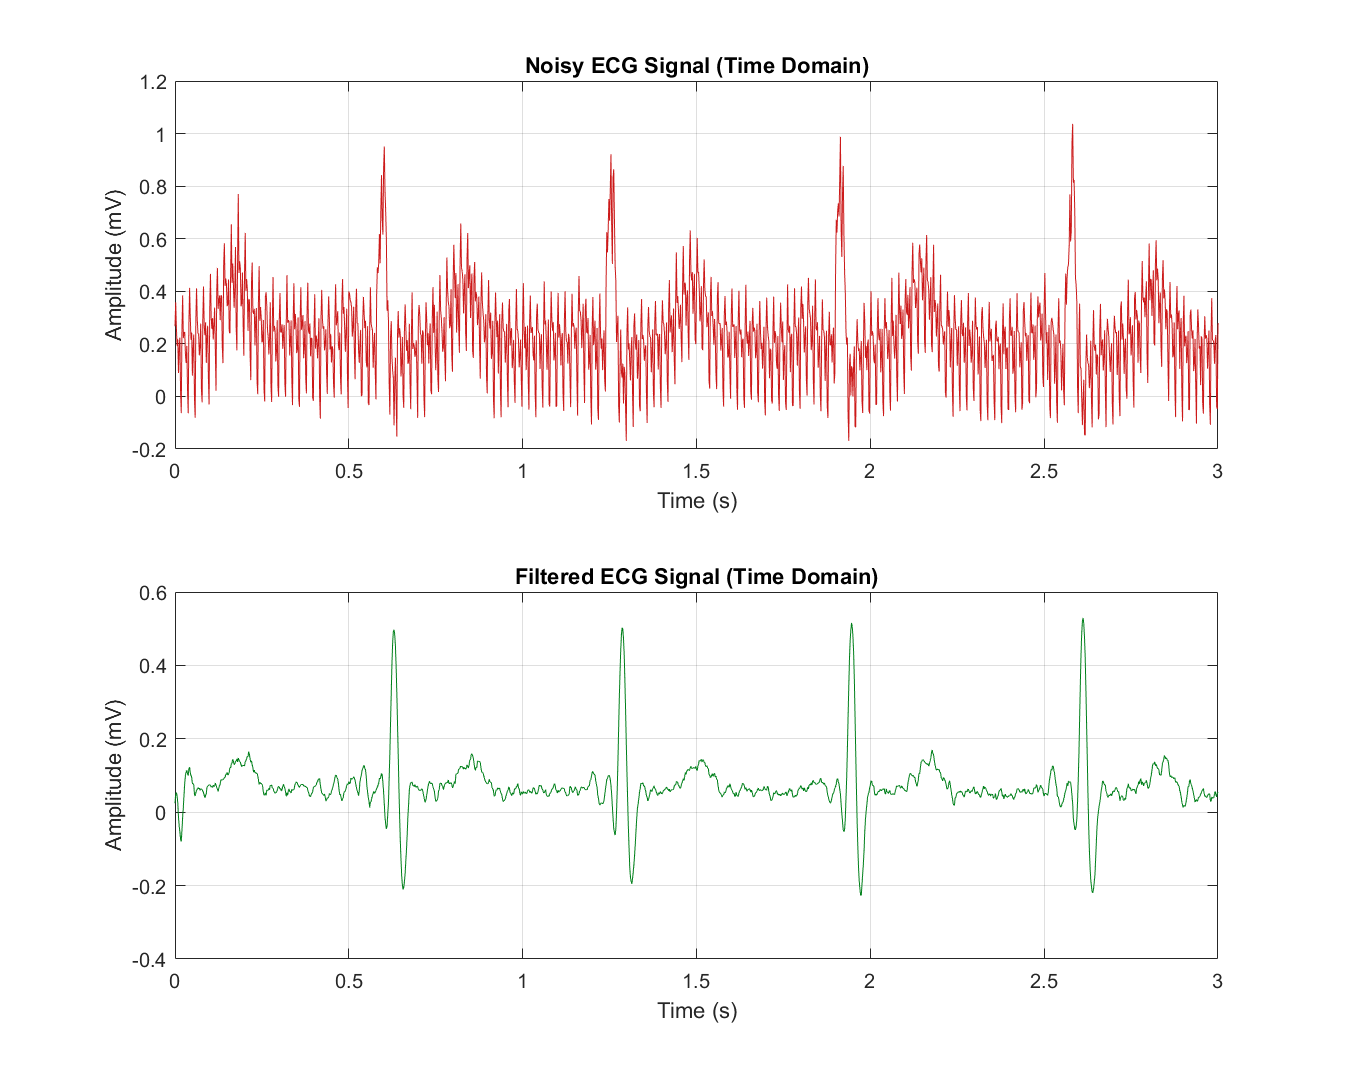

%% (ii) Wiener filter design and application
filter_len = 30;

% Compute cross- and auto-correlation functions
Rxy = xcorr(noisy_seg, clean_seg, filter_len, 'biased');
Rxx = xcorr(noisy_seg, filter_len, 'biased');
Rxx_mat = toeplitz(Rxx(filter_len+1:end));

% Solve Wiener-Hopf equations to find optimal weights
w_opt = Rxx_mat \ Rxy(filter_len+1:end);

% Apply Wiener filter to the full noisy ECG
ecg_noisy_dc = ecg_noisy - mean(ecg_noisy);
ecg_filtered = filter(w_opt, 1, ecg_noisy_dc);

%% (iii) Visualization — time domain comparison
figure('Position', [100, 100, 1000, 800]);

subplot(2,1,1);
plot(t_noisy, ecg_noisy, 'Color', [0.8 0.1 0.1]);
title('Noisy ECG Signal (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
xlim([0 3]); grid on;

subplot(2,1,2);
plot(t_noisy, ecg_filtered, 'Color', [0 0.5 0.1]);
title('Filtered ECG Signal (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
xlim([0 3]); grid on;

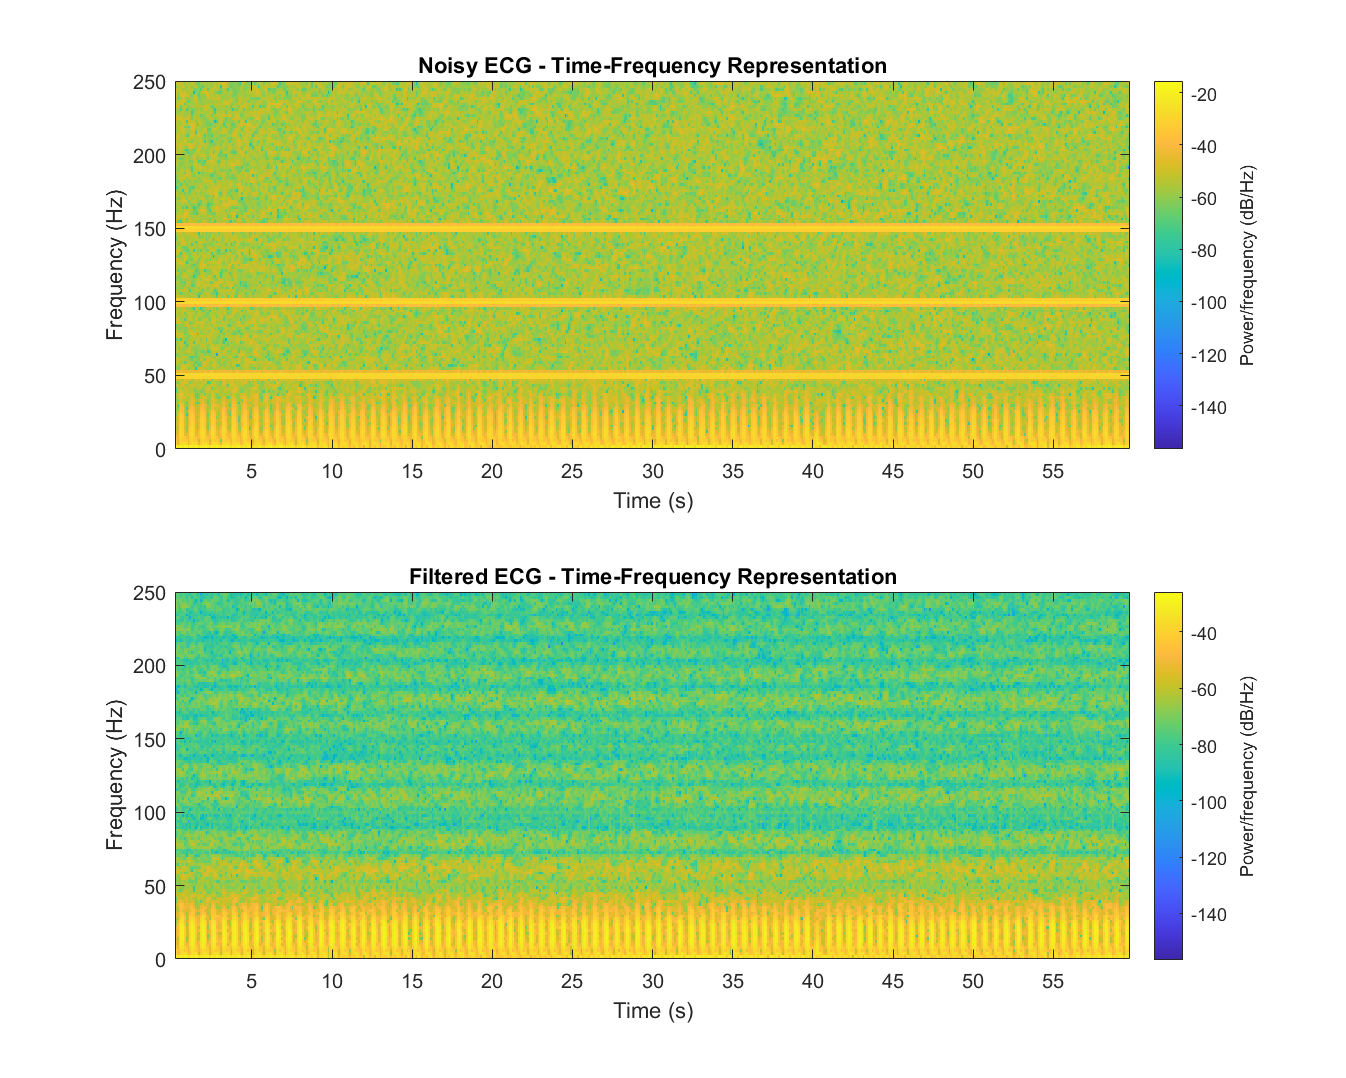



%% (iii) Visualization — time-frequency (spectrogram)

figure('Position', [100, 100, 1000, 800]);

% Duration limit (in seconds)
timeLimit = 60;                        
maxSamples = round(timeLimit * fs_noisy);

% Ensure you don't exceed available signal length
maxSamples = min(maxSamples, length(ecg_noisy));

% Trim signals for plotting only
ecg_noisy_plot = ecg_noisy(1:maxSamples);
ecg_filtered_plot = ecg_filtered(1:maxSamples);

subplot(2,1,1);
spectrogram(ecg_noisy_plot, 256, 200, 256, fs_noisy, 'yaxis');
title('Noisy ECG - Time-Frequency Representation');
ylim([0 250]); 
subplot(2,1,2);
spectrogram(ecg_filtered_plot, 256, 200, 256, fs_noisy, 'yaxis');
title('Filtered ECG - Time-Frequency Representation');
ylim([0 250]); 




save('wiener_weights.mat','w_opt');